clc
clear all
close all
format long;


% % Stationary File Clear
% file_path = "D:\Robotics\2022-02-18-17-18-59.bag"
% % sgtitle('Stationary obstructed')

% Moving File Clear
file_path = "D:\Robotics\2022-02-18-17-31-32.bag"

file_path = "D:\Robotics\2022-02-18-17-31-32.bag"

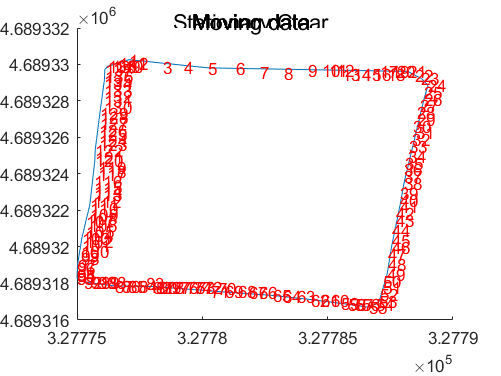

sgtitle('Moving data')

% % Stationary File Obstructed
%  file_path = "D:\Robotics\2022-02-18-18-20-44.bag"
%  % sgtitle('Stationary Obstructed')

% % Moving File Obstructed
% file_path = "D:\Robotics\2022-02-18-18-34-40.bag"
% % sgtitle('Moving data')


bag = rosbag(file_path);
bagInfo = rosbag('info',file_path);
bSel = select(bag,'Topic','gps_data_lab2');
msgStructs = readMessages(bSel,'DataFormat','struct');
%msgStructs{1}
latitudePoints = cellfun(@(m) double(m.Latitude),msgStructs);
longitudePoints = cellfun(@(m) double(m.Longitude),msgStructs);
altitudePoints = cellfun(@(m) double(m.Altitude),msgStructs);
utmEastingPoints = cellfun(@(m) double(m.UtmEasting),msgStructs);
utmNorthingPoints = cellfun(@(m) double(m.UtmNorthing),msgStructs);
qualityPoints = cellfun(@(m) int64(m.Quality),msgStructs);
timePoints_index = cellfun(@(m) int64(m.Header.Seq),msgStructs);
timePoints_index = timePoints_index - min(timePoints_index);
% 
% figure
% plot(timePoints_index, (utmNorthingPoints) ,"red o")
% title('Time vs UTM Northing')
% legend("Northing Points")
% ylabel('Northing(m)')
% xlabel("Time/Data Points")
% std(utmNorthingPoints)
% 
% figure
% plot(timePoints_index, (min(utmEastingPoints) - utmEastingPoints) ,"blue o")
% legend("Easting Points")
% title('Time vs UTM Easting')
% ylabel('Easting(m)')
% xlabel("Time/Data Points")

% figure
% plot(utmEastingPoints,utmNorthingPoints ,"red o" )
% title('UTM Easting vs UTM Northing')
% xlabel("Easting(m)")
% ylabel('Northing(m)')
% 
% 
% figure
% plot(timePoints_index, qualityPoints ,"green o")
% title('Time vs Quality')
% ylabel('Quality')
% 
% figure
% plot(timePoints_index, altitudePoints ,"yellow o")
% title('Time vs Altitude')
% ylabel('Altitude(m)')

% figure
% plot3(min(utmEastingPoints)-utmEastingPoints,min(utmNorthingPoints)-utmNorthingPoints, altitudePoints,'-o' )
% grid on 
% title('UTM Easting vs UTM Northing')
% xlabel("Easting(m)")
% ylabel('Northing(m)')
% zlabel("Altitude(m)")

k = boundary(utmEastingPoints, utmNorthingPoints);
hold on;
plot(utmEastingPoints(k),utmNorthingPoints(k),'-')

% Reference: https://www.mathworks.com/matlabcentral/answers/444937-how-to-plot-index-number-of-a-data-in-the-graph
for kk = 1:length(utmEastingPoints)
    t = text(utmEastingPoints(kk),utmNorthingPoints(kk),num2str(kk));
    t.Color = [1 0 0];
end


figure
hold on;
bsindex = 55;
bendindex = 92;
line_bottom_start = [utmEastingPoints(bsindex) , utmNorthingPoints(bsindex)];
line_bottom_end = [utmEastingPoints(bendindex) , utmNorthingPoints(bendindex)];
fit_model = fit(utmEastingPoints(bsindex:bendindex), utmNorthingPoints(bsindex:bendindex), 'poly1');

error(bsindex:bendindex,1) = point_to_line_distance([utmEastingPoints(bsindex:bendindex), utmNorthingPoints(bsindex:bendindex)] , line_bottom_start , line_bottom_end);
plot(fit_model,utmEastingPoints(bsindex:bendindex),utmNorthingPoints(bsindex:bendindex))

hold on;
rsindex = 25;
rendindex = 54;
line_right_start = [utmEastingPoints(rsindex) , utmNorthingPoints(rsindex)];
line_right_end = [utmEastingPoints(rendindex) , utmNorthingPoints(rendindex)];
fit_model = fit(utmEastingPoints(rsindex:rendindex), utmNorthingPoints(rsindex:rendindex), 'poly1');

error(rsindex:rendindex,1) = point_to_line_distance([utmEastingPoints(rsindex:rendindex), utmNorthingPoints(rsindex:rendindex)] , line_right_start , line_right_end);
plot(fit_model,utmEastingPoints(rsindex:rendindex),utmNorthingPoints(rsindex:rendindex))

hold on;
tsindex = 1;
tendindex = 23;
line_top_start = [utmEastingPoints(tsindex) , utmNorthingPoints(tsindex)];
line_top_end = [utmEastingPoints(tendindex) , utmNorthingPoints(tendindex)];
fit_model = fit(utmEastingPoints(tsindex:tendindex), utmNorthingPoints(tsindex:tendindex), 'poly1');

error(tsindex:tendindex,1) = point_to_line_distance([utmEastingPoints(tsindex:tendindex), utmNorthingPoints(tsindex:tendindex)] , line_top_start , line_top_end);
plot(fit_model,utmEastingPoints(tsindex:tendindex),utmNorthingPoints(tsindex:tendindex))

hold on;
lsindex = 93;
lendindex = 138;
line_left_start = [utmEastingPoints(lsindex) , utmNorthingPoints(lsindex)];
line_left_end = [utmEastingPoints(lendindex) , utmNorthingPoints(lendindex)];
fit_model = fit(utmEastingPoints(lsindex:lendindex), utmNorthingPoints(lsindex:lendindex), 'poly1');

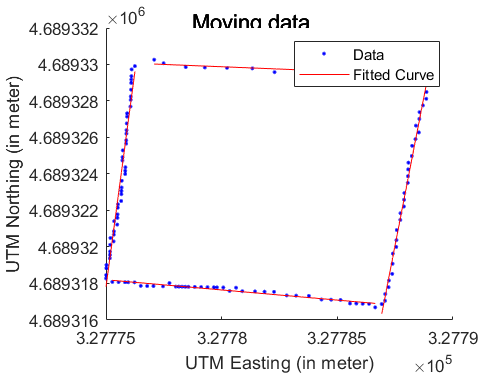

error(lsindex:lendindex,1) = point_to_line_distance([utmEastingPoints(lsindex:lendindex), utmNorthingPoints(lsindex:lendindex)] , line_left_start , line_left_end);
plot(fit_model,utmEastingPoints(lsindex:lendindex),utmNorthingPoints(lsindex:lendindex))
xlabel('UTM Easting (in meter)')
ylabel('UTM Northing (in meter)')
legend('Data','Fitted Curve ','','','')

function distance=point_to_line_distance(pt, v1, v2)
%Calculate distance between a point and a line in 2D or 3D.
% syntax:
% distance = point_to_line(pt, v1, v2)
% pt is a nx3 matrix with xyz coordinates for n points
% v1 and v2 are vertices on the line (each 1x3)
% d is a nx1 vector with the orthogonal distances
%
% 2D inputs are extended to 3D by setting all z-values to 0, all inputs should be either nx2 or nx3
% (1x2 or 1x3 for v1 and v2).
%
% The actual calculation is a slightly edit version of this line (which only works for 3D points):
% distance=norm(cross(v1-v2,pt-v2))/norm(v1-v2)
%
%  _______________________________________________________________________
% | Compatibility | Windows 10  | Ubuntu 20.04 LTS | MacOS 10.15 Catalina |
% |---------------|-------------|------------------|----------------------|
% | ML R2020a     |  works      |  not tested      |  not tested          |
% | ML R2018a     |  works      |  works           |  not tested          |
% | ML R2015a     |  works      |  works           |  not tested          |
% | ML R2011a     |  works      |  works           |  not tested          |
% | ML 6.5 (R13)  |  works      |  not tested      |  not tested          |
% | Octave 5.2.0  |  works      |  works           |  not tested          |
% | Octave 4.4.1  |  works      |  not tested      |  works               |
% """""""""""""""""""""""""""""""""""""""""""""""""""""""""""""""""""""""""
%
% Version: 1.3.2
% Date:    2020-06-28
% Author:  H.J. Wisselink
% Licence: CC by-nc-sa 4.0 ( creativecommons.org/licenses/by-nc-sa/4.0 )
% Email=  'h_j_wisselink*alumnus_utwente_nl';
% Real_email = regexprep(Email,{'*','_'},{'@','.'})

%check inputs
if nargin~=3
    error('HJW:point_to_line_distance:nargin',...
        'Incorrect number of inputs, expected 3.');
end
if ~isnumeric(pt) || ~any(size(pt,2)==[2 3]) || any(size(pt)==0)
    error('HJW:point_to_line_distance:pt_type_size',...
        'First input (pt) is not numeric or has an incorrect shape.')
end
if ~isnumeric(v1) || numel(v1)~=size(pt,2)
    error('HJW:point_to_line_distance:v_type_size',...
        ['Second input (v1) is not numeric or has an incorrect size.',char(10),...
        'Expected 1x3 or 1x2, which should match the first input.']) %#ok<CHARTEN>
end
if ~isnumeric(v2) || numel(v2)~=size(pt,2)
    error('HJW:point_to_line_distance:v_type_size',...
        ['Third input (v2) is not numeric or has an incorrect size.',char(10),...
        'Expected 1x3 or 1x2, which should match the first input.']) %#ok<CHARTEN>
end

%prepare inputs
v1=v1(:)';%force 1x3 or 1x2
v2=v2(:)';%force 1x3 or 1x2
if length(v1)==2,v1(3)=0;  end%extend 1x2 to 1x3 if needed
if length(v2)==2,v2(3)=0;  end%extend 1x2 to 1x3 if needed
if size(pt,2)==2,pt(1,3)=0;end%extend nx2 to nx3 if needed
v1_ = repmat(v1,size(pt,1),1);
v2_ = repmat(v2,size(pt,1),1);

%actual calculation
a = v1_ - v2_;
b = pt - v2_;
distance = sqrt(sum(cross(a,b,2).^2,2)) ./ sqrt(sum(a.^2,2));
%this is equivalent to the following line for a single point
%distance=norm(cross(v1-v2,pt-v2))/norm(v1-v2)
end

